# Numeric square root

This function computes the square root of a given number numerically based on the interval halving (bisection) method.

## Function definition

function sqrtValue = numericSquareRoot(input)

First, we define a relative tolerance constant for the numeric solution.

TOLERANCE_VALUE = 1e-9;

### Handling of complex numbers

If the given input is negative, the result will be a complex number:

isComplex = false;
if input < 0
    input = abs(input);
    isComplex = true;
end

### Interval initialization

The $f\left(x\right)=\sqrt{x}$ square root function is bounded by $f\left(x\right)=1$ constant and $f\left(x\right)=x$ identity functions above $x=1$.

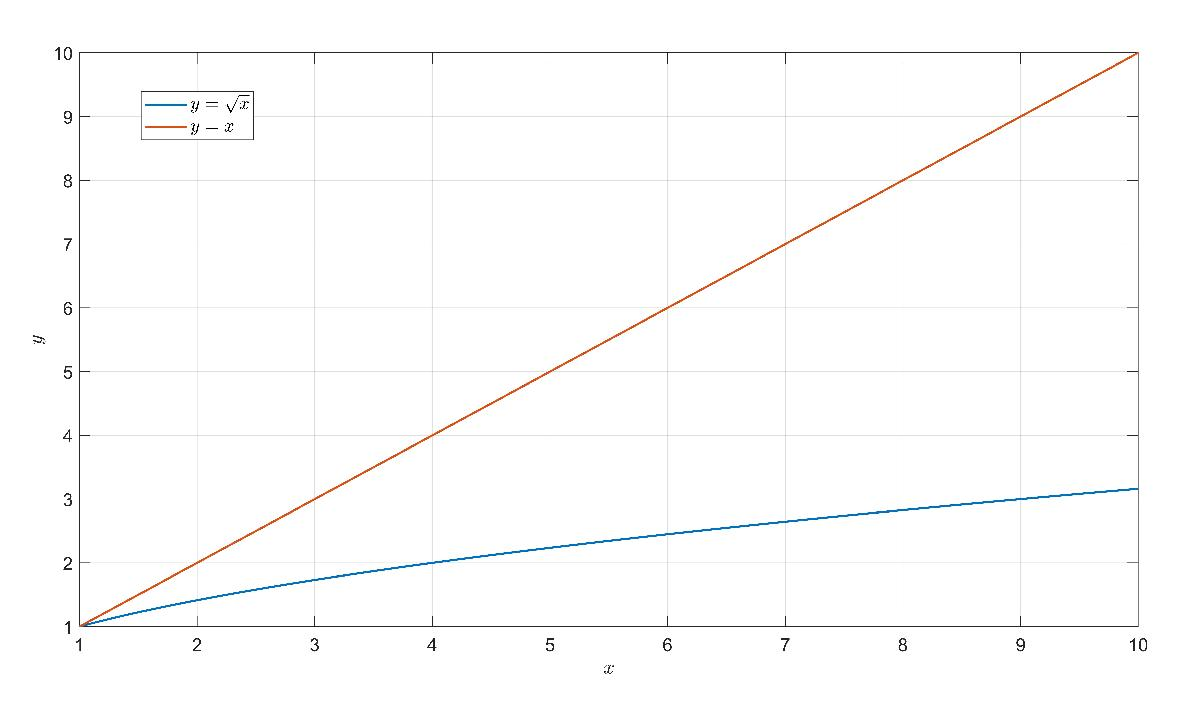

if input > 1
    lower = 1;
    upper = input;

The $f\left(x\right)=\sqrt{x}$ square root function is bounded by the same functions but vice versa.

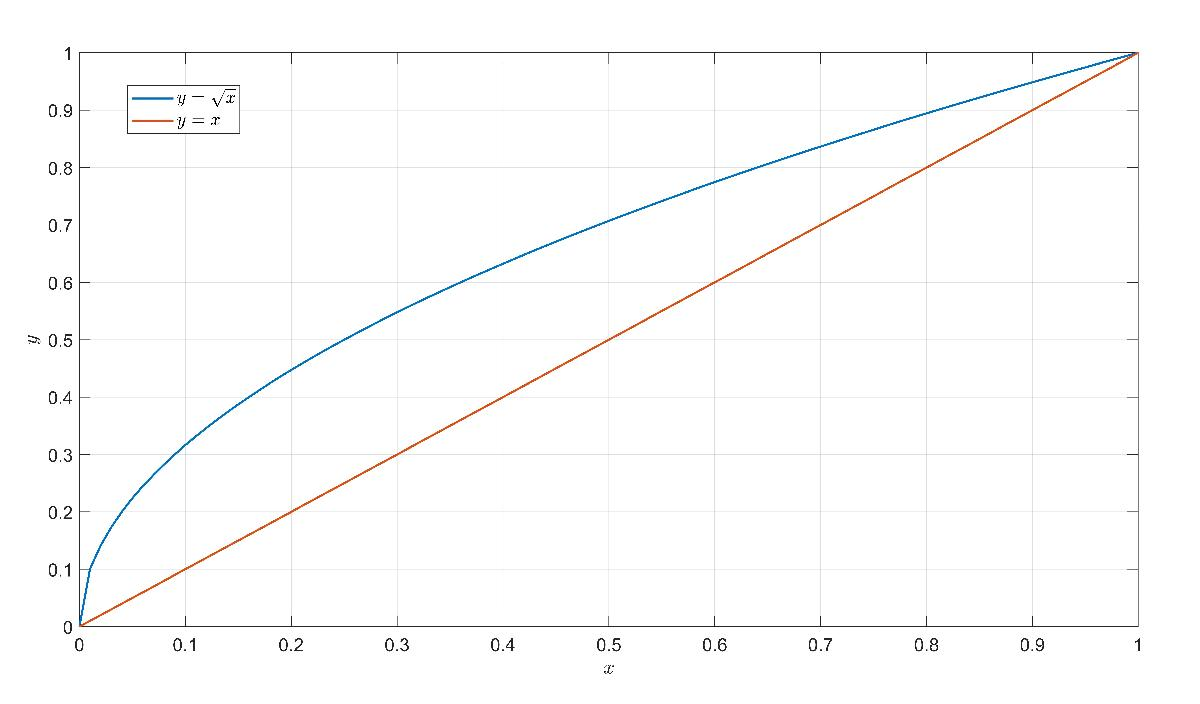

else
    lower = input;
    upper = 1;
end

### Relative tolerance

The relative tolerance is computed based on the pre-defined tolerance constant value to obtain a more precise solution for the lower numbers.

relativeTolerance = input * TOLERANCE_VALUE;

### Interval halving loop

The numeric solution's fitness is investigated by comparing the ${\left({\sqrt{x}}^* \right)}^2$square of the ${\sqrt{x}}^*$ numeric solution and the given number $x$. If their difference is lower than the relative tolerance, the solution is provided numerically within the given tolerance. The boundaries of the interval are modified according to bisection method (for further details open guessingRobot.mlx).

squaredValue = 1;
% relative tolerance
while abs(input - squaredValue) > relativeTolerance
    sqrtValue = (lower + upper) / 2;
    squaredValue = sqrtValue * sqrtValue;
    if squaredValue == input
        break;
    elseif squaredValue < input
        lower = sqrtValue;
    else
        upper = sqrtValue;
    end
end


### Complex result

if isComplex
    sqrtValue = sqrtValue * 1i;
end

end